% linux command to separate vocals and accoompaniemnt
% Usage: spleeter separate [OPTIONS] FILES...

% Separate audio file(s)

%Arguments:
%   FILES...  List of input audio file path  [required]


% This works:
% spleeter separate Abhogi_AjoyC.mp3 Abhogi_PradeepD.mp3 Abhogi_RashidK.mp3 -o ./abhogi_spleeter


% set cwd


if ismac
    % Code to run on Mac platform
    datapath="/Users/studio/Documents/MatlabData"
elseif isunix
    % Code to run on Linux platform
    datapath="/home/ganesh/matlab_r2021b/data_is_here"
elseif ispc
    % Code to run on Windows platform
    homedir = 'G:\My Drive\MATLAB';
    audiodir = append(homedir,"\Audio");
    cd(audiodir);
    currentFolder = pwd
    datapath="C:\MatlabData";
else
    disp('Platform not supported')
end

audiodir = "G:\My Drive\MATLAB\Audio"

currentFolder = 'G:\My Drive\MATLAB\Audio'

datapath = "C:\MatlabData"


% s = settings;
% s.matlab.fonts.editor.normal.Name.PersonalValue = 'Calibri';
% s.matlab.fonts.editor.normal.Size.PersonalValue = 20;
% s.matlab.fonts.codefont.Name.TemporaryValue = 'Arial';

strcat(currentFolder,'/RagaDownloads/Basant/Basant_RashidK.mp3')

ans = 'G:\My Drive\MATLAB\Audio/RagaDownloads/Basant/Basant_RashidK.mp3'

[x, fs] = audioread(strcat(currentFolder,'/RagaDownloads/Basant/Basant_RashidK.mp3'))

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 48000

x1 = x(:,1); %select 1 channel : mono


N = length(x1);
t = (0:N-1)/fs;
plot(t,x1)
grid on
set(gca, 'FontName','Verdana','FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("signal")

[x, fs] = audioread(strcat(currentFolder,'/RagaDownloads/Basant/Basant_spleeter/Basant_RashidK/vocals.wav'))

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

x1 = x(:,1); %select 1 channel : mono

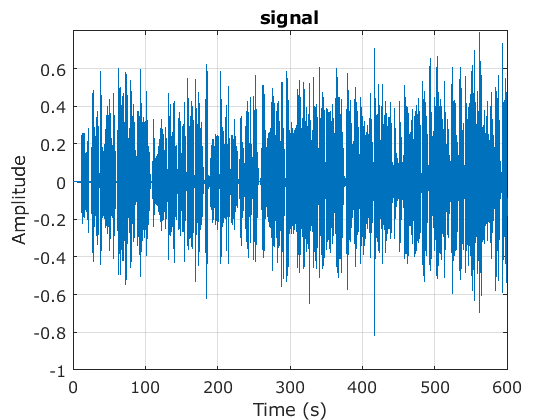

N = length(x1);
t = (0:N-1)/fs;
plot(t,x1)
grid on
set(gca, 'FontName','Verdana','FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("signal")

[x, fs] = audioread(strcat(currentFolder,'/RagaDownloads/Abhogi/Abhogi_RashidK.mp3'))

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 48000

x1 = x(:,1); %select 1 channel : mono


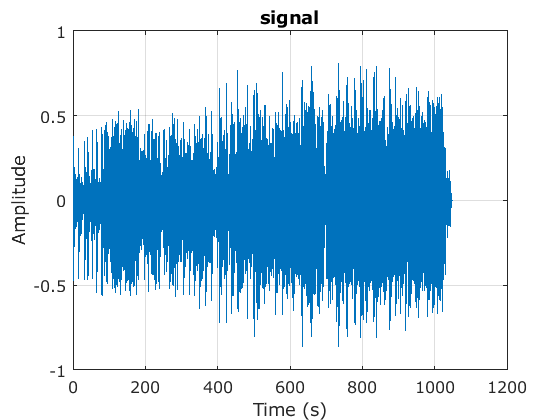

N = length(x1);
t = (0:N-1)/fs;
plot(t,x1)
grid on
set(gca, 'FontName','Verdana','FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("signal")

[x, fs] = audioread(strcat(currentFolder,'/RagaDownloads/Abhogi/abhogi_spleeter/Abhogi_RashidK/vocals.wav'))

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

x1 = x(:,1); %select 1 channel : mono

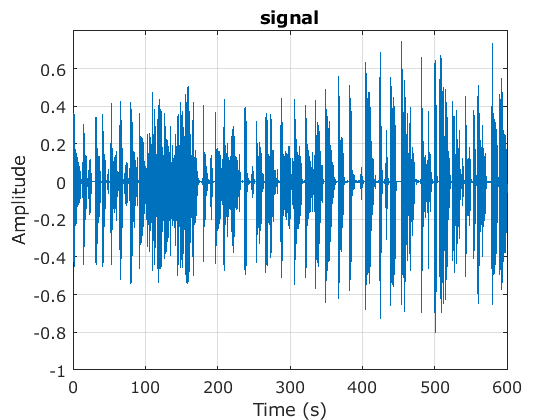

N = length(x1);
t = (0:N-1)/fs;
plot(t,x1)
grid on
set(gca, 'FontName','Verdana','FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("signal")

[x, fs] = audioread(strcat(currentFolder,'/RagaDownloads/Abhogi/abhogi_spleeter/Abhogi_FareedH/vocals.wav'))

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

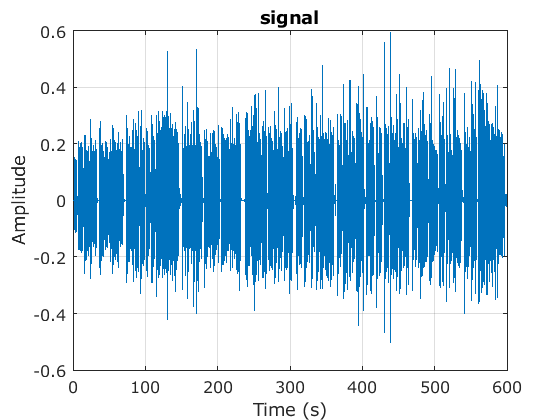

x1 = x(:,1); %select 1 channel : mono
N = length(x1);
t = (0:N-1)/fs;
plot(t,x1)
grid on
set(gca, 'FontName','Verdana','FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("signal")

%sound(x1,fs)
S = audioplayer(x1, fs);
S.play();


S.pause();
%clear sound; %to stop sound wav thats playing